# **WM9QE: Applied Statistics for Artificial Intelligence**

## **Synthetic Data **

This MATLAB Live Script is a suppliment to the Data Collection, Sampling, and Synthetic Data session. Full detail of the lectures and examples are availabe on [Section: Week One | WM9QE:Applied Statistics for Artificial Intelligence | Moodle@Warwick](https://moodle.warwick.ac.uk/course/section.php?id=576666). 

Learning Objectives

- Explain the conceptual principles behind the approaches.

- Understand and implement various synthetic data techniques in MATLAB, providing practical workflows for creating realistic synthetic datasets.

Overview

This tutorial provides hands-on experience with the synthetic data generation techniques covered in the theoretical session: *Distribution-based* and *Simulation-based* methods. Synthetic data plays an increasingly critical role in modern AI systems, where access to real datasets may be restricted due to privacy regulations, limited availability, or cost constraints. By generating artificial yet statistically consistent data, practitioners can train, validate, and stress-test machine learning models in a controlled environment.

# Section 1: Distributed-based Synthetic Data

## **1.1. Overview**

Synthetic data refers to artificially generated data that imitates the statistical or behavioural properties of real-world datasets. It is widely used when access to authentic data is limited due to privacy, cost, or availability constraints. By simulating data generation processes, researchers and engineers can test algorithms, validate models, and explore hypothetical scenarios without depending on sensitive or proprietary information.

Two broad approaches to synthetic data generation are:

- **Distribution-based synthetic data** – samples are drawn from fitted statistical distributions that describe the patterns and variability of the observed data.

- **Simulation-based synthetic data** – data are generated by simulating a process or system governed by physical laws, probabilistic models, or behavioural rules.

**Advantages**

- Enables experimentation when real data are unavailable or confidential.

- Facilitates model validation under controlled conditions.

- Allows scalable data generation with defined statistical properties.

**Limitations**

- May not capture complex dependencies or real-world variability.

- Risk of introducing unrealistic or biased patterns if model assumptions are oversimplified.

- Requires careful validation to ensure the generated data align with intended use cases.

**Typical applications include:**

- Algorithm prototyping and stress testing.

- Machine learning model evaluation and benchmarking.

- Simulation of physical systems, financial scenarios, or medical records.

- Privacy-preserving data sharing and teaching demonstrations.

## **1.2. Distribution-based Synthetic Data**

Distribution-based synthetic data generation assumes that the observed dataset originates from an underlying probability distribution.

The goal is to **estimate the distribution’s parameters** from real data and then **generate new samples** that preserve its essential statistical characteristics.

There are two main modelling strategies:

- **Parametric approaches:** Assume a known functional form, such as Gaussian, exponential, or beta distributions, and estimate parameters (e.g., mean and variance). These are efficient when the data approximately follow a known law.

- **Non-parametric approaches:** Make fewer assumptions about the functional form, instead relying on empirical density estimation (e.g., kernel density or histogram-based methods). These are useful when the data structure is complex or multimodal.

Distribution-based methods are suitable when:

- The data distribution is well understood or can be approximated.

- Generating statistically similar but anonymised records is desired.

- Dependencies between variables can be captured through multivariate or mixture models.

## **1.3. Gaussian (Normal) Distribution**

The Normal Distribution is a continuous probability distribution that is symmetric about the mean, showing that data near the mean are more frequent in occurrence than data far from the mean. It's often called the bell curve because of its characteristic shape.

It's defined by two parameters:

- The **mean** ($\mu $): This determines the center of the distribution.

- The **variance** ($\sigma ^2$) or its square root, the **standard deviation** ($\sigma $): This determines the spread or width of the distribution. A smaller $\sigma $ results in a narrower, taller curve, while a larger σ results in a wider, flatter curve.

Many natural phenomena, like human heights, blood pressure, and measurement errors, follow this distribution.

The probability density function (PDF) for a normal distribution is given by: 


$$f(x)=\frac{1}{\sigma \sqrt{2\pi}}e^{{-\frac{1}{2}}(\frac{x-\mu}{\sigma})^2}$$


The figure below illustrates the bell shape:

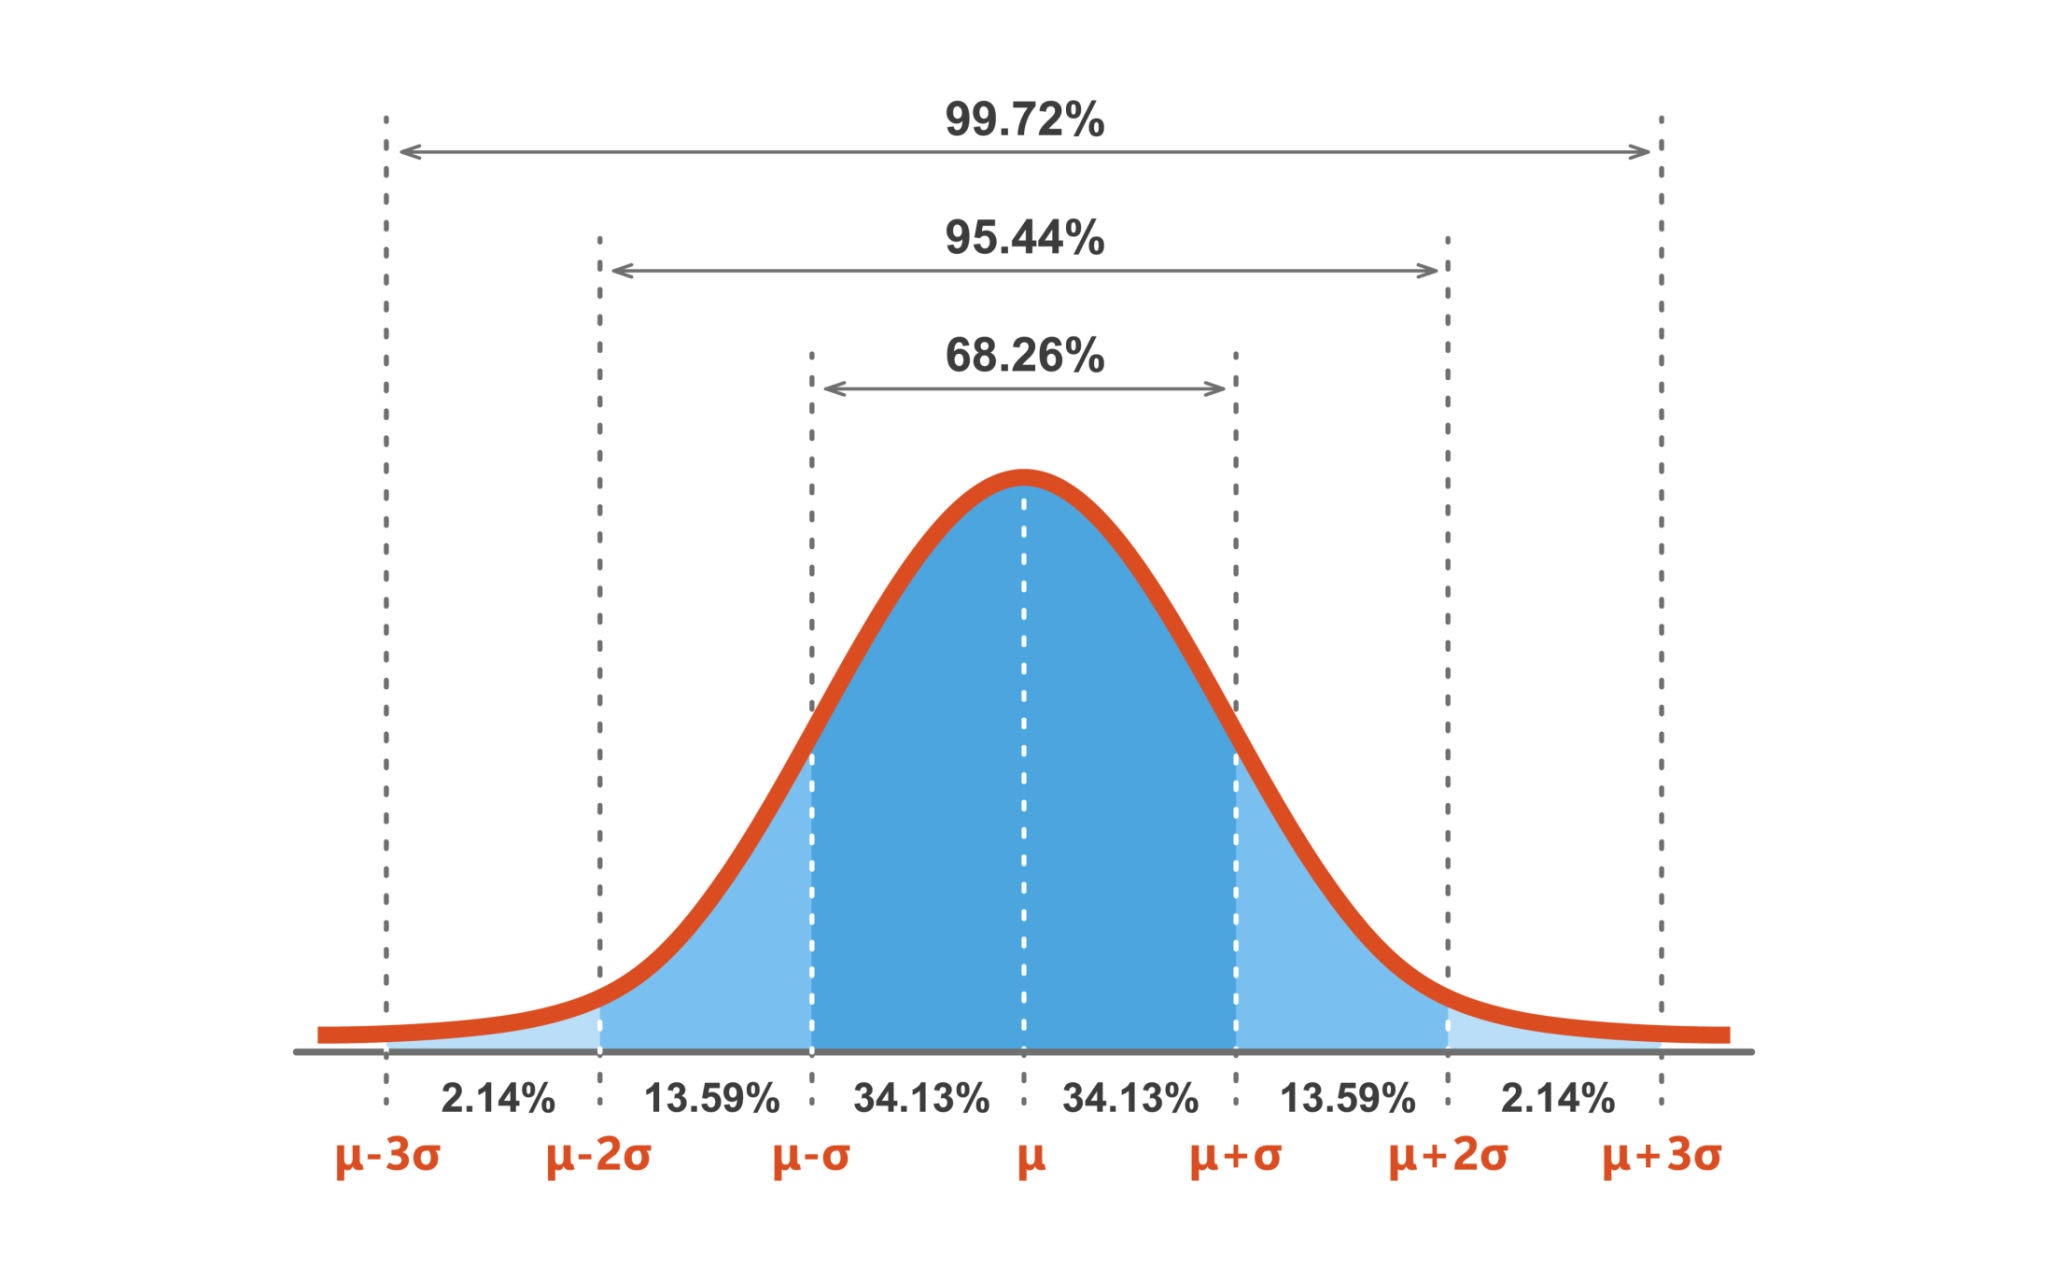

## 1.3.1. Gaussian Distribution Implementation in MATLAB

To implement a Gaussian Distribution in MATLAB, you can generate random numbers that follow the bell-shape distribution using the `randn` function (for standard normal distribution) and then scale and shift them, or use the `normrnd` function (for a specified $\mu $ and $\sigma $).

The following code generates an array of $10,000$ random numbers with a specified mean ($\mu =5$) and standard deviation ($\sigma =2$), and then visualizes its histogram to show the bell shape.

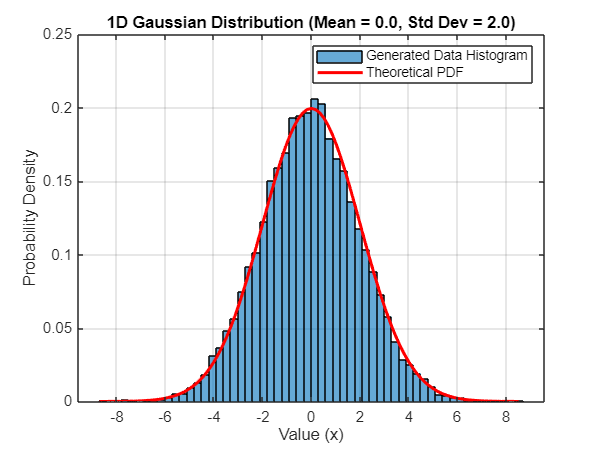

clear; clc; close all;
rng(42); %Seed define for reproducibility

% Define parameters
mu = 0;         % Mean
sigma = 2;      % Standard Deviation (sqrt(variance)=sqrt(4)=2)
N = 10000;      % Number of random samples to generate

% Generate normally distributed random numbers
% normrnd(mu, sigma, rows, cols) generates random numbers from a 
% normal distribution with mean mu and standard deviation sigma.
data_1d = normrnd(mu, sigma, N, 1);

% Create a figure to illustrate the 1D Gaussian concept
figure;
histogram(data_1d, 'Normalization', 'pdf');
hold on;

% Plot the theoretical PDF for comparison
x = linspace(min(data_1d), max(data_1d), 100);
y = normpdf(x, mu, sigma);
plot(x, y, 'r-', 'LineWidth', 2);

title(sprintf('1D Gaussian Distribution (Mean = %.1f, Std Dev = %.1f)', mu, sigma));
xlabel('Value (x)');
ylabel('Probability Density');
legend('Generated Data Histogram', 'Theoretical PDF');
grid on;

**Explanation:**

- `normrnd(mu, sigma, N, 1)`: This function generates an N×1 array (`data_1d`) of random numbers drawn from a normal distribution with the specified mean ($\mu $) and standard deviation ($\sigma $).

- `histogram(..., 'Normalization', 'pdf')`: This plots the frequency distribution of the generated data, scaled so the area under the histogram bars sums to 1, replicating the probability density function (PDF).

- `x = linspace(min(data_1d), max(data_1d), 100): `This defines the domain (the range of x values) over which the theoretical Gaussian curve will be calculated and plotted. It ranges from the minimum to the maximum value of `data_1d` with 100 evenly spaced values.

- `normpdf(x, mu, sigma)`: This calculates the theoretical PDF value for the normal distribution at each point in the vector x, allowing us to superimpose the perfect bell curve onto the histogram for comparison.

## 1.3.2. 2D Gaussian Distribution (Bivariate Normal)

A 2D Gaussian Distribution, also known as the Bivariate Normal Distribution, is an extension of the normal distribution to two variables, typically x and y. It's defined by:

- A **mean vector** $\mu =[\mu_x,\mu_y]$, where $\mu _x$ and $\mu _y$ are the means for the x and y variables, respectively.

- A **covariance matrix** $\Sigma =\left\lbrack {}^{\sigma_x^2 }_{\rho \;\sigma_x \sigma_y }^{\rho \;\sigma_x \sigma_y }_{\sigma_y^2 }\right\rbrack$

- $\sigma_x^2$ and $\sigma_y^2$ are the variances of x and y.

- $\rho$ is the correlation coefficient between x and y. If $\rho=0$, the variables are uncorrelated, and the distribution is an axis-aligned bell-shaped surface.

The resulting distribution is a **bell-shaped surface** in 3D space, which projects onto the xy-plane as elliptical or circular contours.

**MATLAB Implementation with **`mvnrnd`

The MATLAB function `mvnrnd` (Multivariate Normal Random Numbers) is used to generate random numbers from a multivariate normal distribution, which includes the 2D Gaussian as a special case.

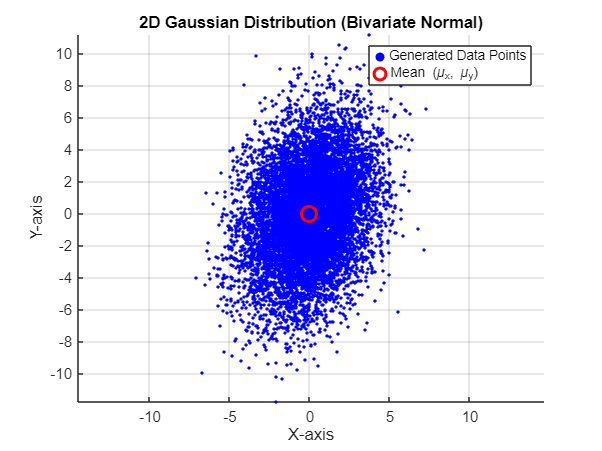

% Define parameters for 2D Gaussian
mu_2d = [0, 0];       % Mean vector [u_x, u_y]
% Covariance matrix Sigma:
% [variance_x, covariance_xy]
% [covariance_xy, variance_y]
variance_x = 4;           % Variance of X (σx²)
variance_y = 9;           % Variance of Y (σy²)
rho = 0.25;
Sigma = [variance_x, rho*sqrt(variance_x*variance_y);
         rho*sqrt(variance_x*variance_y), variance_y];
N_2d = 10000;            % Number of samples

% Generate 2D normally distributed random data
% mvnrnd(mu, Sigma, N) generates N samples from a multivariate 
% normal distribution with mean vector mu and covariance matrix Sigma.
data_2d = mvnrnd(mu_2d, Sigma, N_2d);

% Visualize the 2D distribution using a scatter plot
figure;
scatter(data_2d(:, 1), data_2d(:, 2), 5, 'b', 'filled');
hold on;
plot(mu_2d(1), mu_2d(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2); % Plot the mean

title('2D Gaussian Distribution (Bivariate Normal)');
xlabel('X-axis');
ylabel('Y-axis');
legend('Generated Data Points', 'Mean (\mu_x, \mu_y)');
axis equal;
grid on;

**Explanation of **`mvnrnd(mu_2d, Sigma, N_2d)`: 

- `mu_2d`: The **mean vector** specifies the central location of the distribution in the xy-plane. 

- `Sigma:` The **covariance matrix** dictates the orientation and spread: the diagonal elements (4 and 9) are the variances ($\sigma_x^2$ and $\sigma_y^2$), controlling the spread along the x and y axes, while he off-diagonal elements (1.5 and 1.5) are the covariance ($\rho\sigma_x\sigma_y$), controlling the tilt/rotation of the distribution. A non-zero covariance means x and y are correlated, resulting in an ellipse that's not parallel to the axes.

- `N_2d`: The number of data points to generate.

- The function returns an `N_2d`×2 matrix, where the first column contains the x-coordinates and the second column contains the y-coordinates of the random samples.

Let's look at more 2D Gaussian Distribution examples:

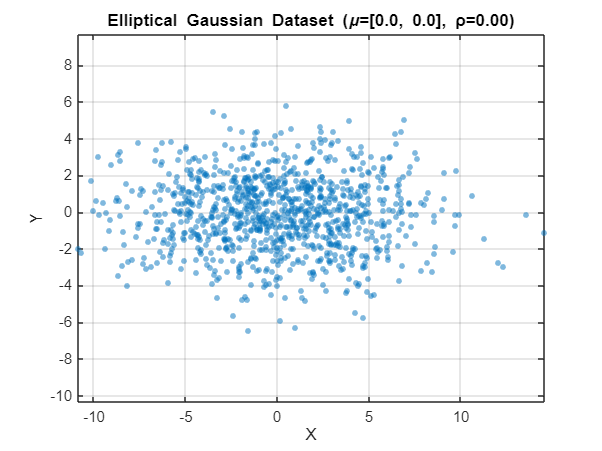

%% Bidimensional Gaussian Data Generator (Circular or Elliptical)
% Generates a 2D synthetic dataset with adjustable means, variances, and correlation

%% === Parameters (modifiable) ===
mu = [0, 0];          % Mean vector [μx, μy]
variance_x = 16;           % Variance of X (σx²)
variance_y = 4;           % Variance of Y (σy²)
rho = 0;              % Correlation between X and Y (-1 ≤ ρ ≤ 1); ρ = 0 creates a circular shape
n_samples = 1000;       % Number of samples

%% === Covariance Matrix ===
% Σ = [σx²      ρσxσy;
%       ρσxσy   σy² ]
Sigma = [variance_x, rho*sqrt(variance_x*variance_y);
         rho*sqrt(variance_x*variance_y), variance_y];

%% === Generate Data ===
data = mvnrnd(mu, Sigma, n_samples);

x = data(:,1); %x-axis distribution
y = data(:,2); %y-axis distribution

%% === Plot 1: Scatter Plot of Samples ===
figure;
scatter(x, y, 15, 'filled', 'MarkerFaceAlpha', 0.5);
title(sprintf('Elliptical Gaussian Dataset (\\mu=[%.1f, %.1f], ρ=%.2f)', mu(1), mu(2), rho));
xlabel('X');
ylabel('Y');
axis equal;
grid on;
box on;

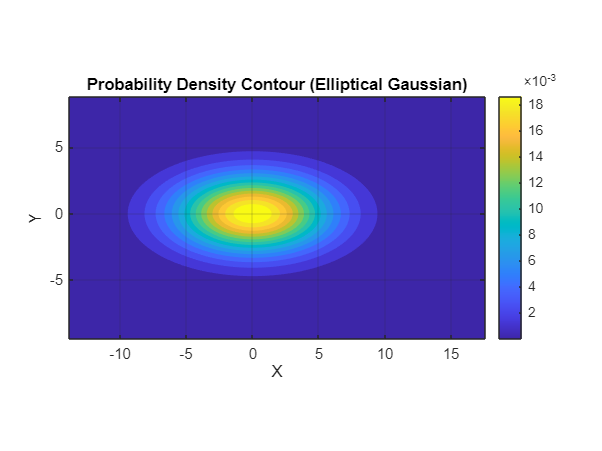


%% === Plot 2: Contour Plot of Probability Density ===
xrange = linspace(min(x)-3, max(x)+3, 150);
yrange = linspace(min(y)-3, max(y)+3, 150);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

pdf_vals = mvnpdf(XY, mu, Sigma);
pdf_vals = reshape(pdf_vals, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_vals, 15, 'LineColor', 'none');
colorbar;
title('Probability Density Contour (Elliptical Gaussian)');
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

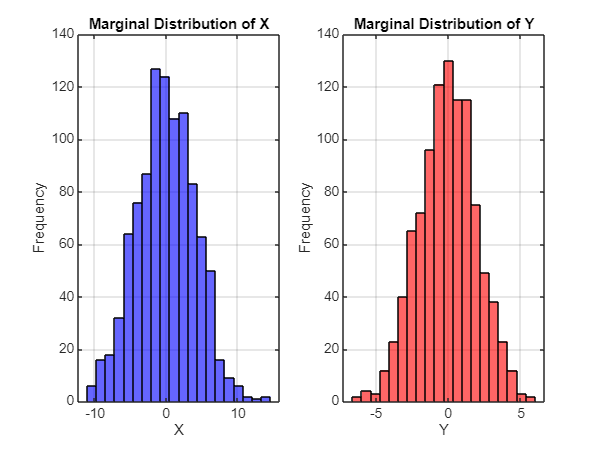


%% === Plot 3: Marginal Distributions (X and Y) ===
figure;
subplot(1,2,1);
histogram(x, 20, 'FaceColor','b', 'FaceAlpha',0.6);
title('Marginal Distribution of X');
xlabel('X'); ylabel('Frequency'); grid on;

subplot(1,2,2);
histogram(y, 20, 'FaceColor','r', 'FaceAlpha',0.6);
title('Marginal Distribution of Y');
xlabel('Y'); ylabel('Frequency'); grid on;

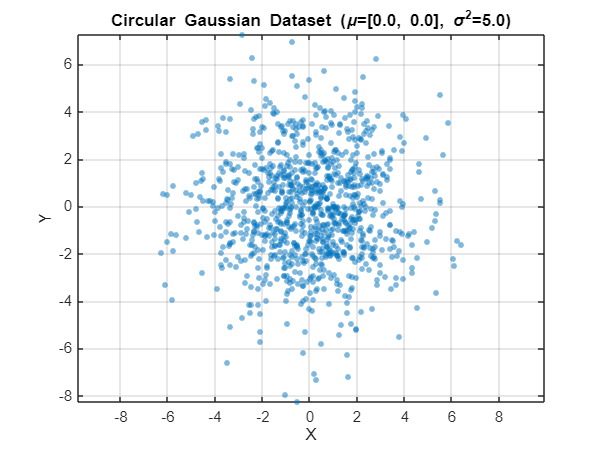

%% Bidimensional Circular Gaussian Data Generator
% Generates a 2D synthetic dataset with adjustable mean and variance

%% === Parameters (modifiable) ===
mu = [0, 0];       % Mean vector [μx, μy]
variance = 5;         % Variance (same for x and y) → circular Gaussian
n_samples = 1000;   % Number of synthetic data points

%% === Covariance Matrix (Circular Gaussian) ===
% For circular distributions: Σ = σ²I (equal variance, zero correlation)
% Where:
%   - σ² is the variance
%   - I is the identity matrix: [1 0; 0 1]
%   - eye(2) creates a 2×2 identity matrix in MATLAB
%   - This creates equal variance in X and Y directions with zero correlation
%   - Result: Σ = [σ² 0; 0 σ²] → circular (isotropic) distribution
Sigma = variance * eye(2);   % Identity scaled by variance → isotropic / circular

%% === Generate Data ===
data = mvnrnd(mu, Sigma, n_samples);

%% === Extract x and y ===
x = data(:,1);
y = data(:,2);

%% === Plot 1: Scatter plot of generated data ===
figure;
scatter(x, y, 15, 'filled', 'MarkerFaceAlpha', 0.5);
title(sprintf('Circular Gaussian Dataset (\\mu=[%.1f, %.1f], \\sigma^2=%.1f)', mu(1), mu(2), variance));
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

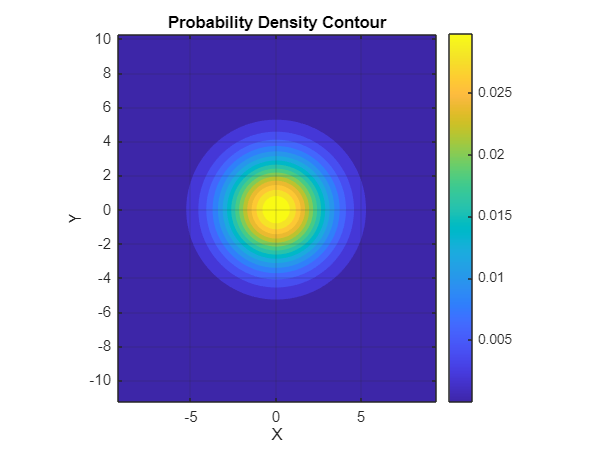


%% === Plot 2: Contour plot of probability density (optional) ===
% Define a grid around the data range
xrange = linspace(min(x)-3, max(x)+3, 100);
yrange = linspace(min(y)-3, max(y)+3, 100);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

% Evaluate Gaussian PDF on the grid
pdf_vals = mvnpdf(XY, mu, Sigma);
pdf_vals = reshape(pdf_vals, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_vals, 15, 'LineColor', 'none');
colorbar;
title('Probability Density Contour');
xlabel('X');
ylabel('Y');
axis equal; grid on; box on;

Let's create a Mikey Mouse Shape:

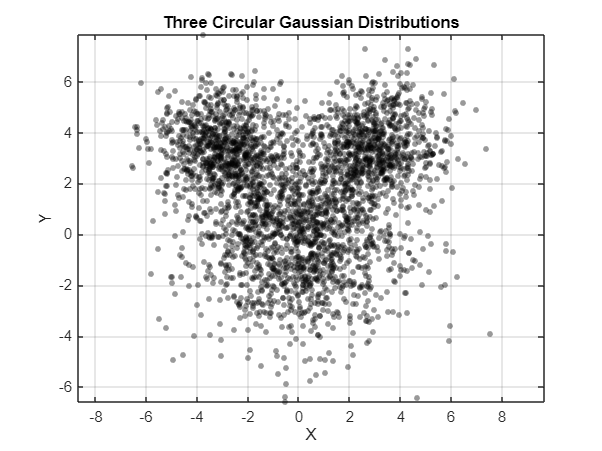

%% Mickey Mouse-like pattern with three circular Gaussians

%% === Parameters for Three Circles ===

% HEAD (large circle at bottom center)
mu_head = [0, 0];           % Center position
var_head = 4;               % Variance (σ²) - controls spread
n_head = 1500;              % Number of samples

% LEFT EAR (smaller circle at top-left)
mu_left_ear = [-3, 3.5];    % Position: left and up
var_ear = 1.44;             % Variance of both ears (smaller than head)
n_ear = 800;                % Number of samples of both ears

% RIGHT EAR (smaller circle at top-right)
mu_right_ear = [3, 3.5];    % Position: right and up
                            % Same variance and n as left ear

% TIP: Adjust variance to control cluster spread
% - SMALLER variance (e.g., 0.5, 1) → tighter, more distinct circles
% - LARGER variance (e.g., 5, 10) → more dispersed, overlapping clusters

%% === Generate Covariance Matrices (Circular) ===
Sigma_head = var_head * eye(2);
Sigma_ear = var_ear * eye(2);

%% === Generate Data for Each Circle ===
data_head = mvnrnd(mu_head, Sigma_head, n_head);
data_left_ear = mvnrnd(mu_left_ear, Sigma_ear, n_ear);
data_right_ear = mvnrnd(mu_right_ear, Sigma_ear, n_ear);

% Combine all data
data_all = [data_head; data_left_ear; data_right_ear];
x_all = data_all(:,1);
y_all = data_all(:,2);

%% === Plot 1: Scatter Plot of All Samples ===
figure;
hold on;
scatter(data_head(:,1), data_head(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(data_left_ear(:,1), data_left_ear(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
scatter(data_right_ear(:,1), data_right_ear(:,2), 15, 'k', 'filled', 'MarkerFaceAlpha', 0.4);
title('Three Circular Gaussian Distributions');
xlabel('X');
ylabel('Y');
axis equal;
grid on;
box on;
hold off;

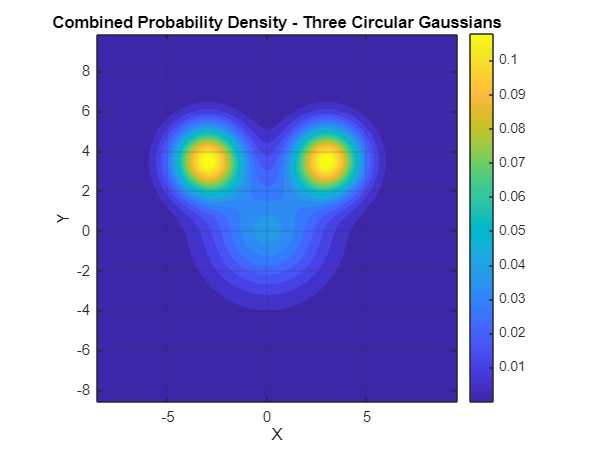


%% === Plot 2: Contour Plot of Combined Probability Density ===
xrange = linspace(min(x_all)-2, max(x_all)+2, 200);
yrange = linspace(min(y_all)-2, max(y_all)+2, 200);
[Xgrid, Ygrid] = meshgrid(xrange, yrange);
XY = [Xgrid(:), Ygrid(:)];

% Calculate combined PDF (sum of three Gaussians)
pdf_head = mvnpdf(XY, mu_head, Sigma_head);
pdf_left = mvnpdf(XY, mu_left_ear, Sigma_ear);
pdf_right = mvnpdf(XY, mu_right_ear, Sigma_ear);
pdf_combined = pdf_head + pdf_left + pdf_right;
pdf_combined = reshape(pdf_combined, size(Xgrid));

figure;
contourf(Xgrid, Ygrid, pdf_combined, 20, 'LineColor', 'none');
colorbar;
title('Combined Probability Density - Three Circular Gaussians');
xlabel('X');
ylabel('Y');
axis equal; 
grid on; 
box on;

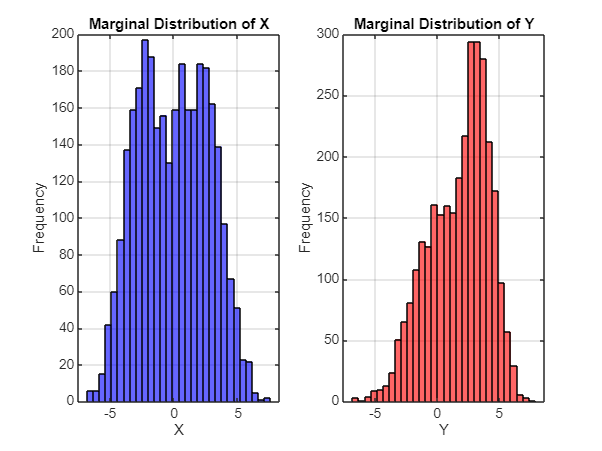


%% === Plot 3: Individual Marginal Distributions ===
figure;
subplot(1,2,1);
histogram(x_all, 30, 'FaceColor','b', 'FaceAlpha',0.6);
title('Marginal Distribution of X');
xlabel('X'); ylabel('Frequency'); grid on;

subplot(1,2,2);
histogram(y_all, 30, 'FaceColor','r', 'FaceAlpha',0.6);
title('Marginal Distribution of Y');
xlabel('Y'); ylabel('Frequency'); grid on;

## **1.4. Gaussian Mixture Model (GMM)**

The GMM is a probabilistic model that represents the probability distribution of observations as a mixture of several underlying component Gaussian distributions. It is a powerful tool for **density estimation** and **clustering**. Instead of assuming all data comes from a single Gaussian distribution (like the bell curve), a GMM assumes the data is generated from a weighted sum (a mixture) of different Gaussian distributions.

Each component Gaussian distribution, $k$, has its own set of parameters:

- **Mean (**$\mu_k$**)**: The center of the $k$-th cluster.

- **Covariance Matrix (**$\Sigma_k$**)**: The spread and orientation of the $k$-th cluster.

- **Mixing Probability (**$\phi_k$**)**: The weight or probability that a data point belongs to the $k$-th component.

The overall probability density function (PDF) of the GMM is:


$$p\left(x\right)=\sum_{k=1}^K \phi_k N\left(x\left|\mu k,\Sigma k\right.\right)$$


where $\sum_{k=1}^K \phi_k =1$.

**Concept Illustration:** A GMM is excellent at modeling data that forms distinct clusters. If you have two groups of people (e.g., short and tall) that are measured for height, the overall height distribution will be a single, non-ideal Gaussian, but a GMM with two components would accurately model the height distribution of the "short group" and the "tall group" separately, combining them into the final distribution.

## 1.4.1. Gaussian Mixture Model Implementation in MATLAB

To implement a GMM, you first need data that is actually generated from a mixture of Gaussians. Then, you use the `fitgmdist` function to estimate the parameters of the underlying components. The code below implements a GMM to learn the statistical structure of the patient multivariate dataset and then uses that learned model to generate new, synthetic data.

%% Synthetic Dataset: Complex Patterns (Using MATLAB Built-in "patients" Dataset)
% Purpose: Generate challenging patterns for algorithm validation
% This is a hybrid strategy: Generate Synthetic data and add it to
% real-world data

%% 1) Load MATLAB built-in dataset: "patients"
load patients   % Contains Age, Height, Weight, etc.

%% 2) Fit Gaussian Mixture Model with 3 components
gmm = fitgmdist([Age, Height, Weight], 3, 'RegularizationValue', 1e-6);

- Data Matrix Creation: `[Age, Height, Weight]` concatenates the three separate data vectors from patients into a single matrix. This matrix has N rows (one for each patient) and 3 columns (features: Age, Height, Weight). This makes the problem a 3D Multivariate GMM.

- `fitgmdist`**:** This function is the core of the GMM implementation. It attempts to find the parameters (means, covariances, and mixing probabilities) of 3 distinct Gaussian distributions (Age, Height, Weight) that best explain the data distribution.

- `3`: Specifies the desired number of component Gaussians (K=3). The model assumes the patient population is composed of 3 hidden subgroups (e.g., perhaps children, healthy adults, and elderly patients).

- `'RegularizationValue', 1e-6`: This is an optional, but often necessary, parameter. It adds a tiny amount of positive bias (10−6) to the diagonal of the covariance matrices. This prevents singularities (matrices becoming non-invertible or having issues) during the Expectation-Maximization (EM) optimization process, especially if clusters are very small or tightly grouped.

- `gmm: `This variable is a GaussianMixtureModel object containing the learned parameters. This object is a **probabilistic model** that has learned the complete statistical structure (the means, covariances, and mixing probabilities) of the original patients dataset. The GMM itself is not a set of data points; it is a mathematical representation of the patients data's distribution.

%% 3) Generate 1000 synthetic samples
n_synthetic = 1000;
synthetic_data = random(gmm, n_synthetic);

synthetic_age    = synthetic_data(:, 1);
synthetic_height = synthetic_data(:, 2);
synthetic_weight = synthetic_data(:, 3);

- `random(gmm, n_synthetic)`: This function uses the probability distribution *learned* by the `gmm` model to randomly generate new, synthetic data points. This function treats the GMM object as a generative model. It essentially asks the model, "If I were to generate new data that follows the exact probability rules you learned from the patients dataset, what would the next 1000 data points look like?" Therefore, it effectively samples 1,000 new patients whose Age, Height, and Weight attributes follow the same statistical rules (means, variances, and correlations) discovered in the original `patients` dataset.

- `synthetic_data` is a 1000×3 matrix.

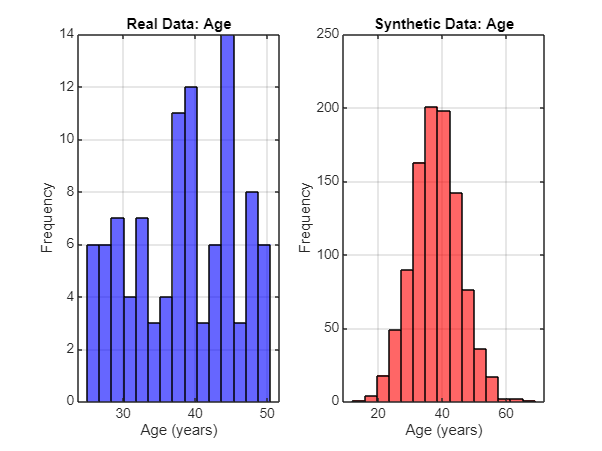

%% 4) Visualisation: Compare Real vs Synthetic Data

% === Figure 1: Age Distribution ===
figure;
subplot(1,2,1);
histogram(Age, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Age');
xlabel('Age (years)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_age, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Age');
xlabel('Age (years)');
ylabel('Frequency');
grid on;

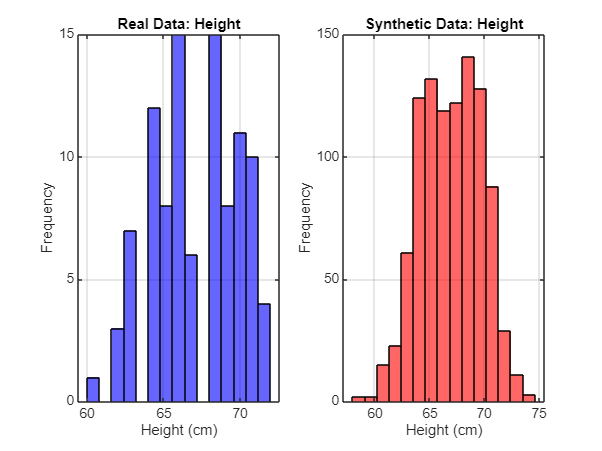


% === Figure 2: Height Distribution ===
figure;
subplot(1,2,1);
histogram(Height, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Height');
xlabel('Height (cm)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_height, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Height');
xlabel('Height (cm)');
ylabel('Frequency');
grid on;

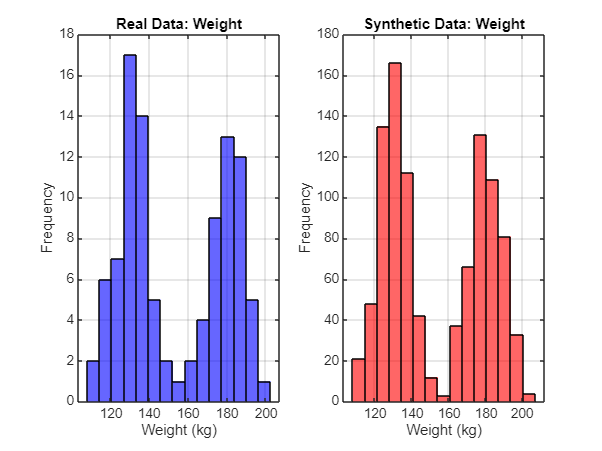


% === Figure 3: Weight Distribution ===
figure;
subplot(1,2,1);
histogram(Weight, 15, 'FaceColor', 'b', 'FaceAlpha', 0.6);
title('Real Data: Weight');
xlabel('Weight (kg)');
ylabel('Frequency');
grid on;

subplot(1,2,2);
histogram(synthetic_weight, 15, 'FaceColor', 'r', 'FaceAlpha', 0.6);
title('Synthetic Data: Weight');
xlabel('Weight (kg)');
ylabel('Frequency');
grid on;

# Section 2: Simulation-based Synthetic Data

Simulation-based synthetic data generation creates artificial datasets by simulating the behaviour of a system—physical, economic, or behavioural—according to a model of its underlying mechanisms. Instead of drawing directly from a fitted probability distribution, we specify state variables, inputs, and dynamics (e.g., differential equations or discrete-time updates), then propagate the system forward in time to produce observables.

A central idea is Monte Carlo simulation: repeat the simulation many times while randomising parameters, initial conditions, or inputs to explore variability and uncertainty. This approach is preferred when:

- Process knowledge (e.g., physics) is available and should constrain the data.

- We need time-series trajectories or causal structure that reflect system dynamics.

- Analytical distributions are unknown or intractable, but a simulator is available.

Benefits include controllable realism, interpretability (through model structure), and the ability to encode constraints (e.g., conservation laws). Limitations include potential model misspecification, computational cost, and sensitivity to unvalidated assumptions.

**System/Process Models & Stochasticity**

A simulation model defines how a system evolves from an initial state under inputs and noise:

- **Deterministic dynamics:** the next state is a fixed function of the current state and inputs. For a continuous-time system ($\dot{\mathbf{x}}(t) = f(\mathbf{x}(t), \mathbf{u}(t), {\theta})$), solutions follow trajectories uniquely determined by initial conditions.

- **Stochastic dynamics:** randomness enters via parameters, disturbances, or measurement noise. A common formulation is a **stochastic differential equation** or a **discrete-time state-space model**: $[\mathbf{x}_{t+1} = g(\mathbf{x}_t, \mathbf{u}_t, {\theta}) + {\varepsilon}_t,\quad\mathbf{y}_t = h(\mathbf{x}_t) + {\eta}_t,]$ where $\varepsilon_t$ and $\eta_t$ represent process and measurement noise.

Parameter uncertainty is captured by sampling $\theta$ from prior distributions, while input variability is captured by sampling input sequences $ \mathbf{u}_{1:T}$. By running many independent trials, we approximate the distribution of outcomes and generate diverse synthetic records with controlled variance.

**Projectile Motion with Randomised Initial Conditions**

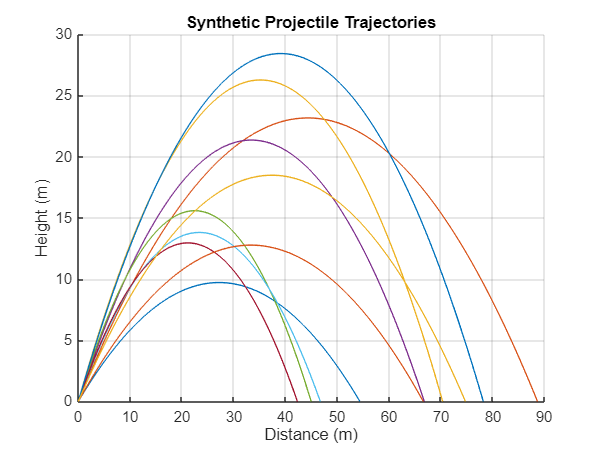

% Generate synthetic data for projectile trajectory prediction
% Parameters
rng(42);

g = 9.81; % gravity (m/s^2)
num_samples = 1000;

% Generate random initial conditions
v0 = 20 + 10*rand(num_samples, 1); % initial velocity (m/s)
theta = 30 + 30*rand(num_samples, 1); % launch angle (degrees)

% Convert to radians
theta_rad = deg2rad(theta);

% Compute trajectory features
t_flight = 2*v0.*sin(theta_rad)/g; % flight time
range_x = v0.^2.*sin(2*theta_rad)/g; % horizontal range
max_height = (v0.*sin(theta_rad)).^2/(2*g); % max height
% Add realistic noise
noise_level = 0.05;
range_x = range_x .* (1 + noise_level*randn(size(range_x)));
max_height = max_height .* (1 + noise_level*randn(size(max_height)));

% Create synthetic dataset
synthetic_data = table(v0, theta, t_flight, range_x, max_height);

% Visualise some trajectories
figure;
hold on;
for i = 1:10
    t = linspace(0, t_flight(i), 100);
    x = v0(i)*cos(theta_rad(i))*t;
    y = v0(i)*sin(theta_rad(i))*t - 0.5*g*t.^2;
    plot(x, y);
end
xlabel('Distance (m)');
ylabel('Height (m)');
title('Synthetic Projectile Trajectories');
grid on;

**System being simulated.**

The block simulates projectile motion under constant gravitational acceleration $g$. For an initial speed $v_0$ and launch angle $\theta$ (in radians), the idealised kinematics (without air resistance) yield:


$$t_{\text{flight}}= \frac{2 v_0 \sin\theta}{g},$$



$$\text{range}_x= \frac{v_0^2 \sin(2\theta)}{g},$$


and


$$h_{\max}= \frac{(v_0 \sin\theta)^2}{2g}$$


Trajectory points satisfy:


$$x(t) = v_0 \cos\theta t,\qquad
y(t) = v_0 \sin\theta  t - \frac{1}{2} g t^2,
$$


valid for $0 \le t \le t_{\text{flight}}$.

**How randomness enters.**

The initial speed and angle are sampled uniformly within specified ranges using the *rand* function, producing diverse starting conditions across trials. Additional Gaussian noise is injected into select outputs (e.g., horizontal range and maximum height) using *randn* to emulate measurement variability or unmodelled effects (such as light aerodynamic perturbations), thereby increasing realism.

**Implementation logic and reproducibility.**

The *rng* function fixes the random seed so that repeated runs recreate identical synthetic datasets—essential for testing and comparative evaluation. The block computes closed-form features $t_{\text{flight}}$, $\text{range}_x$*, *$h_{\max}$ from the sampled $v_0$ and $\theta$. A small set of trajectories is visualised by evaluating$ x(t)$ and$ y(t)$ on a grid of time points per trial.

**Solver selection notes.**

This block uses analytic kinematics, not a numerical ODE solver, which is appropriate because the equations admit closed-form solutions. If the model were extended to include aerodynamic drag or wind, the dynamics would typically become non-linear and possibly stiff; one would then select a numerical integrator such as *ode45* for non-stiff regimes or *ode23s* for stiff regimes. The choice hinges on smoothness and time-scale separation in the extended model.

**From theory to synthetic data.**

The theoretical kinematic equations define the causal structure, Monte Carlo sampling of initial conditions induces variability, Gaussian perturbations inject measurement-like noise, and the resulting dataset preserves physics-consistent relationships (e.g., monotonic dependence of range on $v_0$ at fixed $\theta$) while offering heterogeneous examples for model development.

**Validation & Sensitivity Checks**

To ensure the simulated dataset is credible and fit for purpose:

- **Physics and invariants.**Check that computed features satisfy analytic relationships (e.g.,$t_{\text{flight}} = 2 v_0 \sin\theta / g$) and that units are consistent. Verify non-negativity of heights and that trajectories terminate at ground level.

- **Distributional properties.**Compare empirical distributions of $t_{\text{flight}} $, $\text{range}_x$*, and *$h_{\max}$ against expectations from the input ranges. If inputs are uniform, induced outputs should show characteristic, non-uniform shapes due to the nonlinear mappings.

- **Noise realism.**Evaluate whether the noise level applied via *randn* yields plausible spread without overwhelming the signal. Consider validating measurement noise by comparing coefficient of variation or signal-to-noise ratios to domain knowledge.

- **Sensitivity analysis.**Vary initial-condition ranges, noise amplitudes, and sample sizes to test robustness. Examine how small perturbations to $v_0$ and $\theta$ affect outputs; compute elasticities $\partial \text{range}_x/\partial v_0$ and $\partial \text{range}_x/\partial \theta$ to understand influence.

- **Convergence with repetitions.**Increase the number of Monte Carlo trials and check whether summary statistics (means, variances, quantiles) stabilise—indicative of adequate sampling.

- **Scenario testing.**Run controlled subcases (e.g., fixed $\theta$, varying $v_0$) to confirm qualitative trends (range increases with speed; at fixed speed, range peaks near $\theta = 45^\circ$ in the no-drag model).

- **Time-series integrity.**If exporting trajectories, ensure consistent time grids (using *timetable* and *retime*) and alignment across signals (using *synchronize*) for multi-trial or multi-sensor analyses.

- **Performance scaling.**For large Monte Carlo studies, distribute independent trials using *parfor* to maintain throughput without changing statistical results.

**MATLAB Documentation:**

- `fitdist` — [Fit probability distribution objects to data](https://uk.mathworks.com/help/stats/fitdist.html)

- `mvnrnd` — [Generate multivariate normal random numbers](https://uk.mathworks.com/help/stats/mvnrnd.html)

- `fitgmdist` — [Fit Gaussian mixture models](https://uk.mathworks.com/help/stats/fitgmdist.html)

- `ode45` and `ode23s` — [Solve ordinary differential equations (nonstiff and stiff)](https://uk.mathworks.com/help/matlab/ref/ode45.html)

- `timetable`*, *`retime`*, *`synchronize` — [Manage and align time-stamped data](https://uk.mathworks.com/help/matlab/timetables.html)